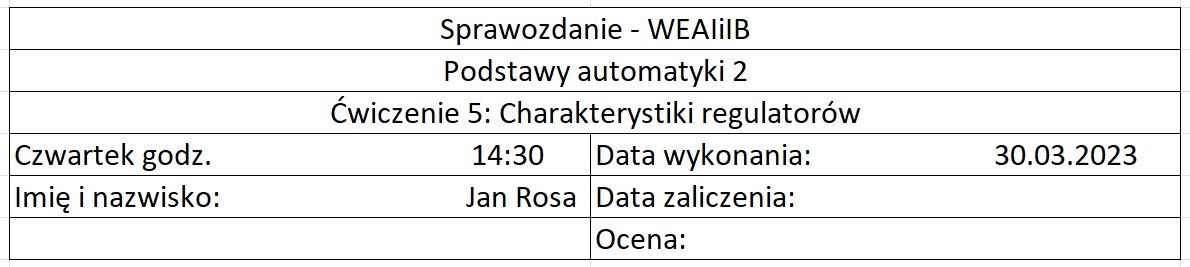 

## PI

k_vec = [0.5 2];
ti_vec = [0.5 2];
t_vec = linspace(0, 10, 100);
obiekty = {};
legendt = {}


legendt =

  0×0 empty cell array



for i = 1:2
    for j = 1:2
        obiekt = k_vec(j) * (1 + tf([0 1], [ti_vec(i) 0]));
        obiekty{2*i + j -2} = obiekt;
        legendt{2*i + j -2} = "k=" +string(k_vec(j)) + ", T_i=" + string(ti_vec(i))
    end
end

legendt = 1×1 cell array
    {["k=0.5, T_i=0.5"]}


legendt = 1×2 cell array
    {["k=0.5, T_i=0.5"]}    {["k=2, T_i=0.5"]}


legendt = 1×3 cell array
    {["k=0.5, T_i=0.5"]}    {["k=2, T_i=0.5"]}    {["k=0.5, T_i=2"]}


legendt = 1×4 cell array
    {["k=0.5, T_i=0.5"]}    {["k=2, T_i=0.5"]}    {["k=0.5, T_i=2"]}    {["k=2, T_i=2"]}


legendt = cell2table(legendt)

legendt = 1×4 table
        legendt1           legendt2          legendt3         legendt4  
    ________________    ______________    ______________    ____________

    "k=0.5, T_i=0.5"    "k=2, T_i=0.5"    "k=0.5, T_i=2"    "k=2, T_i=2"


lnt =      1     4


Error using tabular/length
Undefined function 'LENGTH' for input arguments of type 'table'.  Use the height, width, or size functions instead.

Error in legend (line 154)
        length(args{1})==1 && ...

Error in Lab_5>wykres (line 57)
    legend(legendt)

wykres(obiekty, t_vec, legendt)

PD

k_vec = [0.5 2];
td_vec = [6 21];
tdd_vec = [0.5 2];
t_vec = linspace(0, 10, 100);
obiekty = {};
for i = 1:2
    for j = 1:2
        for k = 1:2
            obiekt = k_vec(j) * (1 + tf([td_vec(i) 0], [tdd_vec(i) 1]));
            obiekty{4*i + 2*j + k - 6} = obiekt;
        end
    end
end
wykres(obiekty, t_vec)

k_vec = [0.5 2];
td_vec = [6 21];
tdd_vec = [0.5 2];
ti_vec = [0.5 2];
t_vec = linspace(0, 10, 100);
obiekty = {};
for i = 1:2
    for j = 1:2
        for k = 1:2
            for l = 1:2
                obiekt = k_vec(j) * (1 + tf([td_vec(i) 0], [tdd_vec(i) 1]) + tf([0 1], [ti_vec(i) 0]));
                obiekty{8*i + 4*j + 2*k + l - 14} = obiekt;
            end
        end
    end
end
wykres(obiekty, t_vec)

function [] = wykres(obiekty, t, legendt)
    lnt = size(obiekty)
    lnt = lnt(2);
    figure();
    %f.Position = [488 342 700 720];
    subplot(3, 1, 1)
    for i = 1:lnt
        step(obiekty{i}, t);
        grid on;
        hold on;
    end
    legend(legendt)
    subplot(3, 1, 2)
    plotooptions = nyquistoptions("cstprefs");
    plotooptions.ShowFullContour = 'off';
    for i = 1:lnt
        nyquist(obiekty{i}, plotooptions);
        grid on;
        hold on;
    end
    legend(legendt)
    subplot(3, 1, 3)
    for i = 1:lnt
        bode(obiekty{i});
        grid on;
        hold on;
    end
    legend(legendt)
end

### Wnioski